%% This script 

clear all
close all

ClusterData=readtable('ClusterData.xlsx');

% Input: ClusterData
% Coloumns:
% 1-4: AnimalID etc
% 5: type (1:pNGF, 2:idNGF, 3:Bi/Ba/ACC, 4:OLM, 5:CCK, 6:Proj., 7:non-NGF, 0:nd)
% 6: layer code (1: s.ori, 2: s.pyr, 3: s.rad, 4: s.lm.)
% 7: Number of spikes during theta
% 8: mTheta
% 9: rTheta
% 10: Number of spikes above threshold during gamma mid
% 11: mGammaMid
% 12: rGammaMid
% 13: Number of spikes above threshold during gamma fast
% 14: mGammaFast
% 15: rGammaFast

incl=zeros(size(ClusterData,1),1);
for je=1:size(ClusterData,1)
    if ~isnan(ClusterData{je, 8}) && ClusterData{je,10}>200 && ClusterData{je,13}>200
        incl(je)=1;
    end
end

mTheta=ClusterData{incl==1,8};
rTheta=ClusterData{incl==1,9};
mGamma=ClusterData{incl==1,11};
rGamma=ClusterData{incl==1,12};
mGammaFast=ClusterData{incl==1,14};
rGammaFast=ClusterData{incl==1,15};

ThetaX=cos(deg2rad(mTheta)).*rTheta;
ThetaY=sin(deg2rad(mTheta)).*rTheta;
GammaX=cos(deg2rad(mGamma)).*rGamma;
GammaY=sin(deg2rad(mGamma)).*rGamma;
GammaFastX=cos(deg2rad(mGammaFast)).*rGammaFast;
GammaFastY=sin(deg2rad(mGammaFast)).*rGammaFast;

LayerID=ClusterData{incl==1,6}-4;

WLengthXY_norm=[ClusterData{incl==1,5} LayerID zscore(ThetaX) zscore(ThetaY) zscore(GammaX) zscore(GammaY) zscore(GammaFastX) zscore(GammaFastY)];


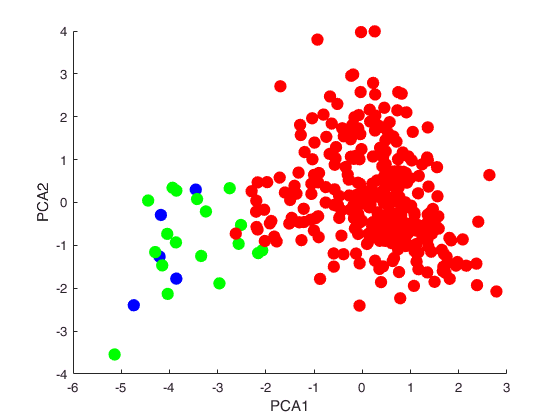

%PCA on the features based on mean vectors of all interneurons to theta, mid-frequency gamma and fast gamma oscillations
figure
[Coeff, Score,~,~,explained]  = pca(WLengthXY_norm(:,3:8));
PCA1=Score(:,1);
PCA2=Score(:,2);
PCA3=Score(:,3);
PCA4=Score(:,4);
PCA5=Score(:,5);
scatter(PCA1(WLengthXY_norm(:,1) == 2),PCA2(WLengthXY_norm(:,1) == 2),1000,'b.')
hold on
scatter(PCA1(WLengthXY_norm(:,1) == 1),PCA2(WLengthXY_norm(:,1) == 1),1000,'g.')
hold on
scatter(PCA1(WLengthXY_norm(:,1) ~= 1 & WLengthXY_norm(:,1) ~= 2),PCA2(WLengthXY_norm(:,1) ~= 1 & WLengthXY_norm(:,1) ~= 2),1000,'r.')
xlabel('PCA1')
ylabel('PCA2')

% find number of principal components explaining >80-85 % variance
over80=find(cumsum(explained)>80);
nPC=over80(1);

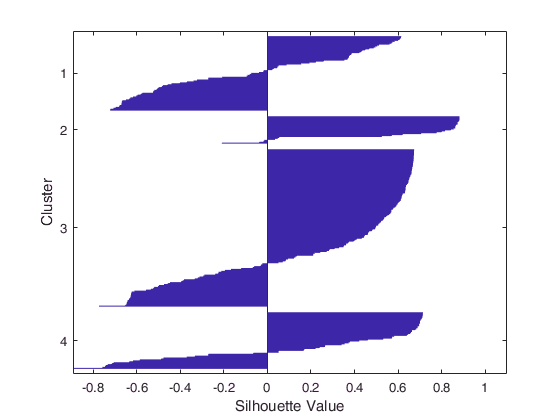

% k-means clustering on the nPC of PC with silhouette analysis to find the opt. number of clusters
figure
for K=1:10
     [IDX{K}, C{K}, SUMD{K}, D{K}] = kmeans([PCA1 PCA2 PCA3 PCA4], K+1);
     [s{K},h] = silhouette([PCA1], IDX{K});
     meanS(K)=mean(s{K});
end

meanS

meanS =          0         0    0.2059


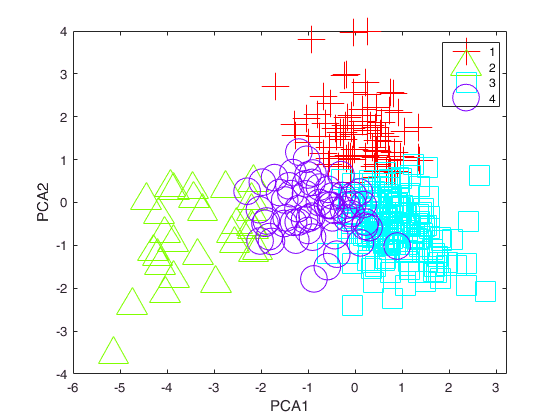

figure
gscatter(PCA1, PCA2, IDX{meanS==max(meanS)}, [], '+^so', 20)